# **Momentum Wheel Equations of Motion Derivation**

## Step 1: Set up all of the state variables and symbols

Currently we will track 2 states of our momentum wheel. 

- roll-angle of the body COM

- angle of the momentum wheel

Then using known parameters from our CAD model we can full define a set of transformations that represent the state of these variables.

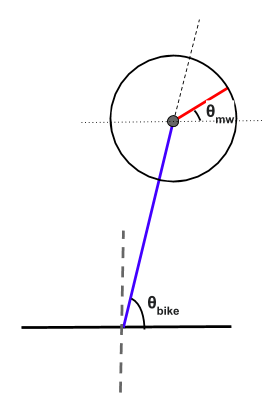

% theta_bike: roll-angle of the bike's CoM
% theta_mw: angle of the Momentum Wheel(MW)
syms theta_bike theta_mw real 

% q: state-variables
q = [theta_bike; theta_mw];

% Generalized velocities: 
% dq: first derivative of state variables w.r.t time
syms dtheta_bike dtheta_mw real 
dq = [dtheta_bike; dtheta_mw];

% Generalized accelerations: 
% ddq: second derivative of state variables w.r.t time
syms ddtheta_bike ddtheta_mw real 
ddq = [ddtheta_bike; ddtheta_mw];

% compute derivatives using chain-rule
derivative = @(in)( jacobian(in,[q;dq])*[dq;ddq] )

derivative = function_handle with value:
    @(in)(jacobian(in,[q;dq])*[dq;ddq])



dtheta_bike = derivative(theta_bike);
dtheta_mw = derivative(theta_mw);

ddtheta_bike = derivative(dtheta_bike);
ddtheta_mw = derivative(dtheta_mw);

% Mass: 
syms m_bike real % mass of the bike
syms m_mw real % mass of the MW

% Moment of Inertia:
syms I_bike real % MoI of the bike
syms I_mw real % MoI of the MW

% Dimensions and Positions: 
syms l_com real % length of CoM above ground
syms offset real % offset between MW and CoM

syms x_com y_com real % x and y position of CoM
syms x_mw y_mw real % x and y position of MW

g = sym('g','real'); % gravity
t = sym('t','real'); % time

x_com = l_com*cos(theta_bike);
y_com = l_com*sin(theta_bike);

x_mw =  (l_com + offset)*cos(theta_bike);
y_mw = (l_com + offset)*sin(theta_bike);

syms dx_com dy_com real
syms dx_mw dy_mw real

dx_com = derivative(x_com);
dy_com = derivative(y_com);
dx_mw = derivative (x_mw);
dy_mw = derivative(y_mw);

syms ddx_com ddy_com real
syms ddx_mw ddy_mw real

ddx_com = derivative(dx_com);
ddy_com = derivative(dy_com);
ddx_mw = derivative (dx_mw);
ddy_mw = derivative(dy_mw);

## Step 2: Set up the transformations 

g_wbike: matrix transformation from the bike's CoM to the world frame

g_wmw:  matrix transformation from the momentum wheel to the world frame

g_wbike = [[cos(theta_bike),-sin(theta_bike), x_com];  %base-frame is the world frame
          [sin(theta_bike),cos(theta_bike), y_com];
          [0, 0, 1]]

$$g\_wbike = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{bike}}\right) & -\sin\left(\theta_{\mathrm{bike}}\right) & l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{bike}}\right)\\ \sin\left(\theta_{\mathrm{bike}}\right) & \cos\left(\theta_{\mathrm{bike}}\right) & l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\\ 0 & 0 & 1 \end{array}\right)$$


g_mw_tran = [[1,0, x_com];  %base-frame is the world frame
              [0,1, y_com];
              [0, 0, 1]]

$$g\_mw\_tran = \left(\begin{array}{ccc} 1 & 0 & l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{bike}}\right)\\ 0 & 1 & l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\\ 0 & 0 & 1 \end{array}\right)$$

g_mw = [[cos(theta_mw+theta_bike),-sin(theta_mw+theta_bike),x_com];
            [sin(theta_mw+theta_bike),cos(theta_mw+theta_bike),y_com];
                [0,0,1]]; 
       
% g_bike_mw = [[cos(-theta_bike),-sin(-theta_bike),0];
%              [sin(-theta_bike),cos(-theta_bike),0];
%              [0,0,1]];   
%          
% g_mw = [[cos(theta_mw-theta_bike),-sin(theta_mw-theta_bike),0];
%              [sin(theta_mw-theta_bike),cos(theta_mw-theta_bike),0];
%              [0,0,1]];  
% g_bike_mw_trans = [[1, 0, x_mw]; 
%             [0, 1, y_mw];
%             [0, 0, 1]];

% g_bike_mw = g_bike_mw_rot*g_bike_mw_trans;
g_wmw = g_mw

$$g\_wmw = \left(\begin{array}{ccc} \cos\left(\theta_{\mathrm{mw}}+\theta_{\mathrm{bike}}\right) & -\sin\left(\theta_{\mathrm{mw}}+\theta_{\mathrm{bike}}\right) & l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{bike}}\right)\\ \sin\left(\theta_{\mathrm{mw}}+\theta_{\mathrm{bike}}\right) & \cos\left(\theta_{\mathrm{mw}}+\theta_{\mathrm{bike}}\right) & l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\\ 0 & 0 & 1 \end{array}\right)$$


vector_g_wbike = g_wbike(:);
vector_g_wmw = g_wmw(:);

g_row = sqrt(numel(g_wmw));
g_column = sqrt(numel(g_wmw));
g_size = [g_column, g_row];

diff_g_wbike = reshape(derivative(vector_g_wbike), g_size); %d(g_wbike)/dt
diff_g_wmw = reshape(derivative(vector_g_wmw), g_size); %d(g_wmw)/dt

% Velocity vectors(hat):
V_bike = g_wbike\diff_g_wbike;
V_mw = g_wmw\diff_g_wmw;

unhat_V_bike = simplify([V_bike(1,3); V_bike(2,3); V_bike(2,1)])

$$unhat\_V\_bike = \left(\begin{array}{c} 0\\ {\mathrm{dtheta}}_{\mathrm{bike}}\,l_{\mathrm{com}}\\ {\mathrm{dtheta}}_{\mathrm{bike}} \end{array}\right)$$

unhat_V_mw = simplify([V_mw(1,3); V_mw(2,3); V_mw(2,1)])

$$unhat\_V\_mw = \left(\begin{array}{c} {\mathrm{dtheta}}_{\mathrm{bike}}\,l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{mw}}\right)\\ {\mathrm{dtheta}}_{\mathrm{bike}}\,l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{mw}}\right)\\ {\mathrm{dtheta}}_{\mathrm{mw}}+{\mathrm{dtheta}}_{\mathrm{bike}} \end{array}\right)$$


% Mass matrice:
G_bike = [[m_bike, 0, 0]; % bike's mass matrix
         [0, m_bike, 0]; 
         [0, 0, I_bike]];

G_mw = [[m_mw, 0, 0]; % momentum wheel's mass matrix
        [0, m_mw, 0]; 
        [0, 0, I_mw]];

## Step 3: Compute the Kinetic and Potential Energies

%the bike consists of rotational and linear kinetic energies
KE_bike =  simplify(0.5*unhat_V_bike'*G_bike*unhat_V_bike);
%the momentum wheel consists of only a rotational energy
KE_mw = simplify(0.5*unhat_V_mw'*G_mw*unhat_V_mw);

%total kinetic energy 
KE = simplify(KE_bike + KE_mw)

$$KE = \frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,\left(m_{\mathrm{bike}}\,{l_{\mathrm{com}}}^{2}+I_{\mathrm{bike}}\right)}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{mw}}}^{2}}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}}{2}+\frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}}{2}+I_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{bike}}$$

%because MW's mass is included in the bike, total potential energy is
PE = simplify(m_bike * g * g_wbike(2,3)+m_mw * g * g_wmw(2,3))

$$PE = g\,l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\,\left(m_{\mathrm{bike}}+m_{\mathrm{mw}}\right)$$

% PE = simplify(m_mw * g * g_wmw(2,3))
syms Energy real
Energy = KE + PE

$$Energy = \frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,\left(m_{\mathrm{bike}}\,{l_{\mathrm{com}}}^{2}+I_{\mathrm{bike}}\right)}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{mw}}}^{2}}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}}{2}+\frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}}{2}+I_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{bike}}+g\,l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\,\left(m_{\mathrm{bike}}+m_{\mathrm{mw}}\right)$$

matlabFunction(Energy,'File','autogen_energy');

## Step 4: Caclulate the LHS of the EL Equations

Now that we have the Kinetic and Potential Energies, we can get the Legrangian and find the Euler Legrange Equations for the bike.

% Euler-Langrangian Equation
L = KE - PE

$$L = \frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,\left(m_{\mathrm{bike}}\,{l_{\mathrm{com}}}^{2}+I_{\mathrm{bike}}\right)}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{mw}}}^{2}}{2}+\frac{I_{\mathrm{mw}}\,{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}}{2}+\frac{{{\mathrm{dtheta}}_{\mathrm{bike}}}^{2}\,{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}}{2}+I_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{mw}}\,{\mathrm{dtheta}}_{\mathrm{bike}}-g\,l_{\mathrm{com}}\,\sin\left(\theta_{\mathrm{bike}}\right)\,\left(m_{\mathrm{bike}}+m_{\mathrm{mw}}\right)$$


% Deriving Euler Lagragian equations
del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d/dt(del L/del dq)
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_qdot = jacobian(KE,dq)';
ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;dq])*[dq;ddq])

$$ELeq\_term1 = \left(\begin{array}{c} I_{\mathrm{mw}}\,{\mathrm{ddtheta}}_{\mathrm{mw}}+{\mathrm{ddtheta}}_{\mathrm{bike}}\,\left(I_{\mathrm{bike}}+I_{\mathrm{mw}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}\right)\\ I_{\mathrm{mw}}\,\left({\mathrm{ddtheta}}_{\mathrm{mw}}+{\mathrm{ddtheta}}_{\mathrm{bike}}\right) \end{array}\right)$$

ELeq_term2 = simplify(jacobian((KE-PE),q))'

$$ELeq\_term2 = \left(\begin{array}{c} -g\,l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{bike}}\right)\,\left(m_{\mathrm{bike}}+m_{\mathrm{mw}}\right)\\ 0 \end{array}\right)$$

## Step 5: Build the Constraints

Now to simulate our momentum wheel behave like one on a real bike. We need to apply the following constraints:

% Constraints
Con = sym('Con',[numel(q), 1],'real'); %constraint matrix

% Constraint so that the back wheel effects the x position of the COM
c_com = x_com^2 + y_com^2 -l_com^2

$$c\_com = {l_{\mathrm{com}}}^{2}\,{\cos\left(\theta_{\mathrm{bike}}\right)}^{2}+{l_{\mathrm{com}}}^{2}\,{\sin\left(\theta_{\mathrm{bike}}\right)}^{2}-{l_{\mathrm{com}}}^{2}$$


C_all = [c_com];

matlabFunction(C_all,'File','autogen_constraints');
% A-matrix and H:
A_all = jacobian(C_all, q) %A-matrix for constraint

$$A\_all = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

H_com = hessian(c_com, q) 

$$H\_com = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

matlabFunction(A_all,H_com,'File','autogen_constraint_derivatives');

## Step 6: Define the External Forces

The function of the momentum wheel is to produce a torque counteracting the torque of the bike falling due to the gravity. In Q, the external force on theta_bike is equal and opposite to that on theta_mw. 

Q = sym('Q', [numel(q),1],'real');
syms tau_mw real;

Q = [0;tau_mw];

## Step 7: Caclulate our M, C, and G

These are the last components needed to solve for our equations of motion.

%computing Mass matrix
M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');


M = simplify(jacobian(del_L_del_qdot,dq))

$$M = \left(\begin{array}{cc} I_{\mathrm{bike}}+I_{\mathrm{mw}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}} & I_{\mathrm{mw}}\\ I_{\mathrm{mw}} & I_{\mathrm{mw}} \end{array}\right)$$

H = simplify(jacobian(del_L_del_qdot,q)*dq - ELeq_term2)

$$H = \left(\begin{array}{c} g\,l_{\mathrm{com}}\,\cos\left(\theta_{\mathrm{bike}}\right)\,\left(m_{\mathrm{bike}}+m_{\mathrm{mw}}\right)\\ 0 \end{array}\right)$$


Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M))

$$Minv = \left(\begin{array}{cc} \frac{1}{I_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}} & -\frac{1}{I_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}}\\ -\frac{1}{I_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}} & \frac{I_{\mathrm{bike}}+I_{\mathrm{mw}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}}{I_{\mathrm{mw}}\,\left(I_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{bike}}+{l_{\mathrm{com}}}^{2}\,m_{\mathrm{mw}}\right)} \end{array}\right)$$


matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H_eom');
fprintf("Done Deriving Equations!")

Done Deriving Equations!